## Dynamic identification

clc;
clearvars;
load('IdentDyn.mat');
yw = DataDynW(:,2);
yc = DataDynC(:,2);
u = DataDynW(:,1);
phi = zeros(length(yw), 2);
for n = 2:length(yw)
    phi(n,:) = [yw(n-1) u(n-1)];
end

phic = zeros(length(yc), 2);
for n = 2:length(yc)
    phic(n,:) = [yc(n-1) u(n-1)];
end


P = phi'*phi\phi'*yw

P =     0.8976
    0.1889


Pc = phic'*phic\phic'*yc

Pc =     0.8521
    0.2326


Tp = 0.05;
%P(1) = exp(-Tp/T)
% P(2) = k*(1-exp(-Tp/T))

% white noise parameters
T = -Tp/log(P(1))

T = 0.4629

k = P(2)/(1-exp(-Tp/T))

k = 1.8445


% color noise parameters 
Tc = -Tp/log(Pc(1))

Tc = 0.3124

kc = Pc(2)/(1-exp(-Tp/Tc))

kc = 1.5730


% error of estimation in percent

yhatw = phic*P;
erw = (yw - yhatw)*100;

yhatc = phic*Pc;
erc = (yc - yhatc)*100;

for 50% data

Due to the number of data in yw is odd, I dropped the last data since it has more effect.

zlen = (length(yw)-1)/2;
Ze = zeros(zlen, 1);
uz = zeros(zlen, 1);
for n = 1:zlen
    Ze(n, 1) = yw(2*n-1);
    uz(n, 1) = u(2*n-1);
end

phiz = zeros(zlen, 2);
for n = 2:length(Ze)
    phiz(n,:) = [Ze(n-1) uz(n-1)];
end

Pe = (phiz'*phiz)\phiz'*Ze

Pe =     0.7892
    0.3698


Te = -Tp/log(Pe(1))

Te = 0.2112

ke = Pe(2)/(1-exp(-Tp/Te))

ke = 1.7543


%% the rest values are used as a valuation data
Zv = zeros(zlen, 1);
uv = zeros(zlen, 1);
for n = 1:zlen
    Zv(n, 1) = yw(2*n);
    uv(n, 1) = u(2*n);
end

% the new phi using the validation data
phiv = zeros(zlen, 2);
for n = 2:zlen
    phiv(n,:) = [Zv(n-1) uv(n-1)];
end

% error between the validation data and the estimated
ywvhat = phiv*Pe;
errv = Zv - ywvhat;
max(errv)

ans = 0.4551

min(errv)

ans = -0.3472

Plots of errors

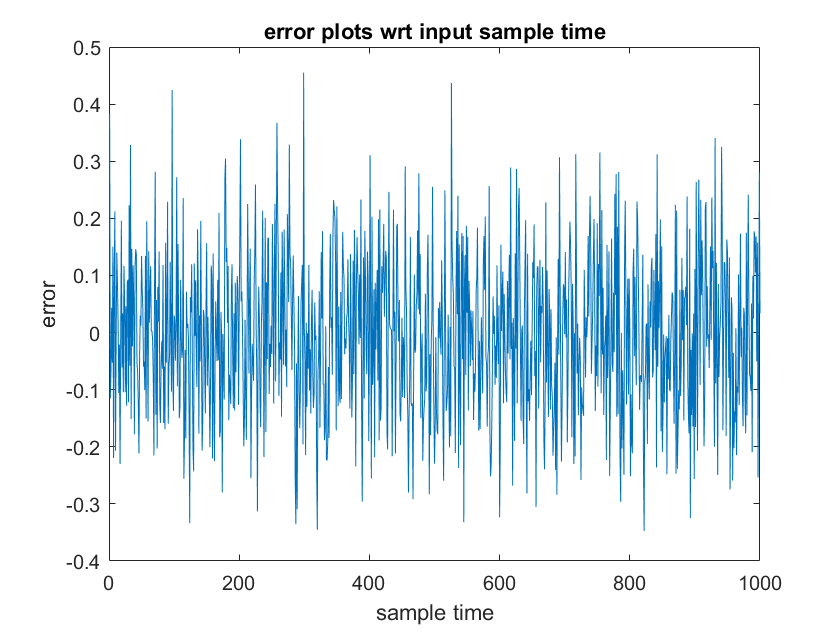

plot(errv)
title("error plots wrt input sample time")
ylabel("error")
xlabel("sample time")